# Capacity Factor and Power Replacement 

Description: This algorithm calculates the capacity equivalent to replace the fossil power in place and for the scenario of expansion of the power sector

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2021

clc
clear
close all

## Load Data

load Data_EIA.mat

## Variables

% Electricity installed capacity (million kW)
El_Cap_Tot=Data_EIA.El_Cap_Tot(:,21:end);%[GW]
% nuclear electricity installed capacity (million kW)
El_Cap_Nuc=Data_EIA.El_Cap_Nuc(:,21:end);%[GW]
% fossil fuels electricity installed capacity (million kW)
El_Cap_Fos=Data_EIA.El_Cap_Fos(:,21:end);%[GW]
% renewable electricity installed capacity (million kW)
El_Cap_Ren=Data_EIA.El_Cap_Ren(:,21:end);%[GW]
% hydroelectricity installed capacity (million kW)
El_Cap_Hyd=Data_EIA.El_Cap_Hyd(:,21:end);%[GW]
% geothermal electricity installed capacity (million kW)
El_Cap_Geo=Data_EIA.El_Cap_Geo(:,21:end);%[GW]
% solar electricity installed capacity (million kW)
El_Cap_Sol=Data_EIA.El_Cap_Sol(:,21:end);%[GW]
% wind electricity installed capacity (million kW)
El_Cap_Win=Data_EIA.El_Cap_Win(:,21:end);%[GW]
% biomass and waste electricity installed capacity (million kW)
El_Cap_Bio=Data_EIA.El_Cap_Bio(:,21:end);%[GW]

% Electricity Generation
% electricity net generation (billion kWh)
El_Gen_Tot=Data_EIA.El_Gen_Tot(:,21:end);%[TWh]
% nuclear electricity net generation (billion kWh)
El_Gen_Nuc=Data_EIA.El_Gen_Nuc(:,21:end);%[TWh]
% fossil fuels electricity net generation (billion kWh)
El_Gen_Fos=Data_EIA.El_Gen_Fos(:,21:end);%[TWh
% renewable electricity net generation (billion kWh)
El_Gen_Ren=Data_EIA.El_Gen_Ren(:,21:end);%[TWh]
% hydroelectricity net generation (billion kWh)
El_Gen_Hyd=Data_EIA.El_Gen_Hyd(:,21:end);%[TWh]
% geothermal electricity net generation (billion kWh)
El_Gen_Geo=Data_EIA.El_Gen_Geo(:,21:end);%[TWh]
% solar electricity net generation (billion kWh)
El_Gen_Sol=Data_EIA.El_Gen_Sol(:,21:end);%[TWh]
% wind electricity net generation (billion kWh)
El_Gen_Win=Data_EIA.El_Gen_Win(:,21:end);%[TWh]
% biomass and waste electricity net generation (billion kWh)
El_Gen_Bio=Data_EIA.El_Gen_Bio(:,21:end);%[TWh]

% Electricity production from coal sources (% of total)
El_F_Coal=Data_EIA.El_F_Coal(:,21:end);
% Electricity production from natural gas sources (% of total)
El_F_Gas=Data_EIA.El_F_Gas(:,21:end);
% Electricity production from oil sources (% of total)
El_F_Oil=Data_EIA.El_F_Oil(:,21:end);
% 1980:2015

Year=2000:2017;

% Colormap
Color=[85,200,60       % Biomass 0,104,55  
      55,55,55          % Fossil
      202,0,32          % Geothermal
      33,102,172        % Hydro
      128,115,172        % Nuclear
      255,199,44      % Solar 244,109,67 
      146,197,222]/255; % Wind 


% From EIA
%Total World	Installed coal-fired generating capacity: [GW]
% 2010:2050 up tp 2017
W_El_Cap_Coal=[1593.6649	1672.3734	1742.8409	1802.5896...
	1876.973	1957.9339	2027.8577	2086.9423	2104.0165...
	2126.8143	2153.7694	2159.7448	2165.6024	2167.6395...
	2169.5158	2173.0731	2179.5206	2187.6071	2197.2746...
	2208.4714	2217.3036	2202.0152	2184.2036	2171.561...
	2156.0182	2143.3758	2134.6261	2124.7156	2115.9661...
	2107.2147	2098.4606	2096.8062	2096.3669	2095.3652...
	2094.927	2094.4912	2115.7467	2137.0039	2158.2602...
	2179.5166	2200.772];
%Total World	Installed liquids-fired generating capacity: 
W_El_Cap_Oil=[290.6505	295.3858	298.0867	303.1172	308.9278...
	309.1566	309.6275	353.6116	333.4196	315.0393 296.942...
	278.2492	264.1795	250.4885	235.4895	222.1089 211.8806...
	204.7907	197.4233	189.212	182.644	178.4611 174.7192	170.4113...
	166.2585	162.0866	159.1842	156.5818 153.7575	151.1551...
	148.5527	147.4493	146.1709	145.2895 144.4082	143.401	143.4877...
	143.5746	143.6614	143.7483 143.8351];
%Total World	Installed natural-gas-fired generating capacity: 
W_El_Cap_gas=[1359.7427	1403.1716	1451.6739	1485.3259	1551.6345...
	1578.6068	1582.8705	1631.9297	1643.8534	1650.8136	1661.7834...
	1680.6414	1692.3999	1706.9281	1725.0204	1744.9503	1795.1432...
	1847.168	1894.506	1940.8896	1992.7392	2065.4649	2142.4198...
	2216.6554	2293.9924	2364.9939	2410.1708	2458.613	2500.9513...
	2547.3938	2594.0358	2631.3688	2667.3042	2703.2581	2741.3491...
	2780.8447	2832.0197	2879.8347	2931.1013	2980.8333	3031.498];

% Capacity Factor
% Biomass
CF_Bio=El_Gen_Bio(1,:)./(El_Cap_Bio(1,:)/1000*24*365);
% Fossil
CF_Fos=El_Gen_Fos(1,:)./(El_Cap_Fos(1,:)/1000*24*365);
% Nuclear
CF_Nuc=El_Gen_Nuc(1,:)./(El_Cap_Nuc(1,:)/1000*24*365);
% Renewables
CF_Ren=El_Gen_Ren(1,:)./(El_Cap_Ren(1,:)/1000*24*365);
% Total
CF_Tot=El_Gen_Tot(1,:)./(El_Cap_Tot(1,:)/1000*24*365);
% Geothermal
CF_Geo=El_Gen_Geo(1,:)./(El_Cap_Geo(1,:)/1000*24*365);
% Hydro
CF_Hyd=El_Gen_Hyd(1,:)./(El_Cap_Hyd(1,:)/1000*24*365);
% Solar
CF_Sol=El_Gen_Sol(1,:)./(El_Cap_Sol(1,:)/1000*24*365);
% Wind
CF_Win=El_Gen_Win(1,:)./(El_Cap_Win(1,:)/1000*24*365);


## Capacity Factor Max, Min and STD


% Max Mean Min STD CI95
Max_Mean_Min_Bio=[nanmax(CF_Bio) nanmean(CF_Bio) nanmin(CF_Bio) nanstd(CF_Bio) 1.96*nanstd(CF_Bio)/length(CF_Bio(~isnan(CF_Bio)))];
Max_Mean_Min_Fos=[nanmax(CF_Fos) nanmean(CF_Fos) nanmin(CF_Fos) nanstd(CF_Fos) 1.96*nanstd(CF_Fos)/length(CF_Fos(~isnan(CF_Fos)))];
Max_Mean_Min_Geo=[nanmax(CF_Geo) nanmean(CF_Geo) nanmin(CF_Geo) nanstd(CF_Geo) 1.96*nanstd(CF_Geo)/length(CF_Geo(~isnan(CF_Geo)))];
Max_Mean_Min_Hyd=[nanmax(CF_Hyd) nanmean(CF_Hyd) nanmin(CF_Hyd) nanstd(CF_Hyd) 1.96*nanstd(CF_Hyd)/length(CF_Hyd(~isnan(CF_Hyd)))];
Max_Mean_Min_Nuc=[nanmax(CF_Nuc) nanmean(CF_Nuc) nanmin(CF_Nuc) nanstd(CF_Nuc) 1.96*nanstd(CF_Nuc)/length(CF_Nuc(~isnan(CF_Nuc)))];
Max_Mean_Min_Sol=[nanmax(CF_Sol) nanmean(CF_Sol) nanmin(CF_Sol) nanstd(CF_Sol) 1.96*nanstd(CF_Sol)/length(CF_Sol(~isnan(CF_Sol)))];

Max_Mean_Min_Win=[nanmax(CF_Win) nanmean(CF_Win) nanmin(CF_Win) nanstd(CF_Win) 1.96*nanstd(CF_Win)/length(CF_Win(~isnan(CF_Win)))];

% Organize as a single vector
CF_Max=[Max_Mean_Min_Bio(1) Max_Mean_Min_Fos(1) Max_Mean_Min_Geo(1) Max_Mean_Min_Hyd(1)...
    Max_Mean_Min_Nuc(1) Max_Mean_Min_Sol(1) Max_Mean_Min_Win(1)];
CF_Mean=[Max_Mean_Min_Bio(2) Max_Mean_Min_Fos(2) Max_Mean_Min_Geo(2) Max_Mean_Min_Hyd(2)...
    Max_Mean_Min_Nuc(2) Max_Mean_Min_Sol(2) Max_Mean_Min_Win(2)];
CF_Min=[Max_Mean_Min_Bio(3) Max_Mean_Min_Fos(3) Max_Mean_Min_Geo(3) Max_Mean_Min_Hyd(3)...
    Max_Mean_Min_Nuc(3) Max_Mean_Min_Sol(3) Max_Mean_Min_Win(3)];
CF_STD=[Max_Mean_Min_Bio(4) Max_Mean_Min_Fos(4) Max_Mean_Min_Geo(4) Max_Mean_Min_Hyd(4)...
    Max_Mean_Min_Nuc(4) Max_Mean_Min_Sol(4) Max_Mean_Min_Win(4)];
CF_CI95=[Max_Mean_Min_Bio(5) Max_Mean_Min_Fos(5) Max_Mean_Min_Geo(5) Max_Mean_Min_Hyd(5)...
    Max_Mean_Min_Nuc(5) Max_Mean_Min_Sol(5) Max_Mean_Min_Win(5)];
leg={'$$\mathrm{Biomass}$$';'$$\mathrm{Fossil}$$';'$$\mathrm{Geoth.}$$';'$$\mathrm{Hydro}$$';...
    '$$\mathrm{Nuclear}$$';'$$\mathrm{Solar}$$';'$$\mathrm{Wind}$$'};


## Nominal capacity Equivalent

Fos_Eq=CF_Mean.\CF_Mean(2);
Ideal_Eq=1./CF_Mean;

% Get Uncertainties
CF_per=CF_STD./CF_Mean;
CF_STD_per_Cor=CF_per+CF_per(2);
CF_STD_Fos=Fos_Eq.*CF_STD_per_Cor;% STD for Decarbonization
CF_STD_Ideal=Ideal_Eq.*CF_per;% STD for Growth


## Plot Figure

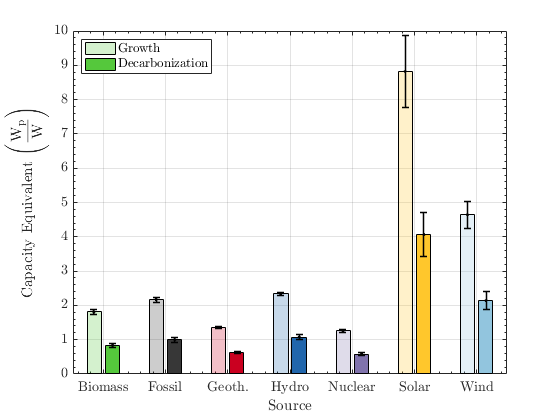

figure('Name','Equivalent Ideal Replacement')
hold on
h1=bar([1 2 3 4 5 6 7],[Ideal_Eq;Fos_Eq]);
errorbar([1 2 3 4 5 6 7]-0.15,Ideal_Eq,CF_STD_Ideal,CF_STD_Ideal,'.k','linewidth',1.5,'HandleVisibility','off')
errorbar([1 2 3 4 5 6 7]+0.15,Fos_Eq,CF_STD_Fos,CF_STD_Fos,'.k','linewidth',1.5,'HandleVisibility','off')
% Color Growth
h1(1).FaceColor = 'flat';
h1(1).FaceAlpha=0.25;
h1(1).CData(1,:) = Color(1,:);
h1(1).CData(2,:) = Color(2,:);
h1(1).CData(3,:) = Color(3,:);
h1(1).CData(4,:) = Color(4,:);
h1(1).CData(5,:) = Color(5,:);
h1(1).CData(6,:) = Color(6,:);
h1(1).CData(7,:) = Color(7,:);
% Color Decarbonization
h1(2).FaceColor = 'flat';
h1(2).FaceAlpha=1;
h1(2).CData(1,:) = Color(1,:);
h1(2).CData(2,:) = Color(2,:);
h1(2).CData(3,:) = Color(3,:);
h1(2).CData(4,:) = Color(4,:);
h1(2).CData(5,:) = Color(5,:);
h1(2).CData(6,:) = Color(6,:);
h1(2).CData(7,:) = Color(7,:);
xticklabels(categorical(leg))
xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Equivalent~\Bigg(\frac{W_p}{W}\Bigg)}$$','interpreter','latex')
box on
grid on
xtickangle(0)
legend('Growth','Decarbonization','Interpreter','latex','Location','NW')
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.25,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-dpng','-r400','CF_Rep.png')